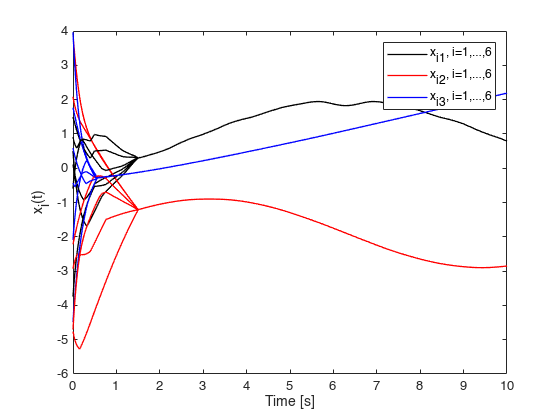

global L d n
n = 6;
m = 8;
d = 3;
gamma = 1;
rng(3);

s = [1 1 2 2 3 3 4 5];
t = [2 4 3 5 4 6 5 6];
G = graph(s,t);
H = incidence(G)'*eye(6);
A12 = [1 0 0; 0 2 1; 0 1 2];
A25 = eye(3); A34 = A25;
A14 = [2 2 0; 2 2 0; 0 0 1];
A36 = A14;
A23 = [2 0 0; 0 0 0; 0 0 1];
A56 = A23;
A45 = [0 0 0; 0 1 0; 0 0 2];

W = blkdiag(A12,A14,A23,A25,A34,A36,A45,A56);

Hbar = kron(H,eye(d));
L = Hbar'*W*Hbar;

x0 = 10*(rand(d*n,1)-0.5);
options = odeset('RelTol',1e-7,'AbsTol',1e-6);

% Disturbance-observer based Matrix-weighted consensus
[t,r] = ode45(@smc_consensus, [0:0.01:10], x0, options);
r = r';
x = r(1:d*n,:);

e = zeros(length(t),1);
for i=1:length(t)
    e(i,1) = norm(L*x(:,i));
end

figure
hold on;
for i=1:n
   plot(t,x(3*i-2,:),'-k','LineWidth',1);
   plot(t,x(3*i-1,:),'-r','LineWidth',1);
   plot(t,x(3*i,:),'-b','LineWidth',1);
end
xlabel 'Time [s]'; ylabel 'x_i(t)';
box on;
legend({'x_{i1}, i=1,\ldots,6','x_{i2}, i=1,\ldots,6','x_{i3}, i=1,\ldots,6'},"NumColumns",1)

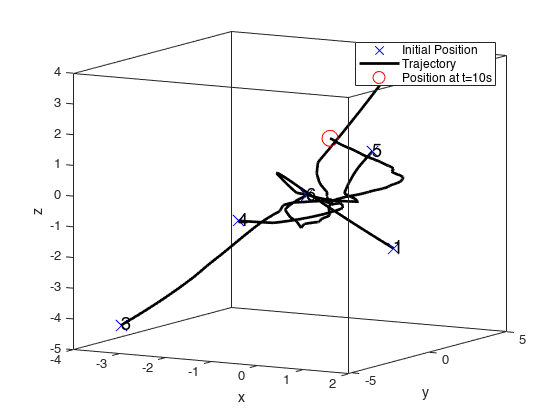


figure
hold on;
for i=1:n
   plot3(x(3*i-2,1),x(3*i-1,1),x(3*i,1),'xb','MarkerSize',12);
   plot3(x(3*i-2,:),x(3*i-1,:),x(3*i,:),'-k','LineWidth',2);
   plot3(x(3*i-2,end),x(3*i-1,end),x(3*i,end),'or','MarkerSize',12);
   text(x(3*i-2,1),x(3*i-1,1),x(3*i,1),num2str(i),"FontSize",14);
end
xlabel 'x'; ylabel 'y'; zlabel 'z';
ax = gca;
ax.BoxStyle = 'full';
box on
legend({'Initial Position','Trajectory','Position at t=10s'}, "NumColumns", 1)
view(30,10)

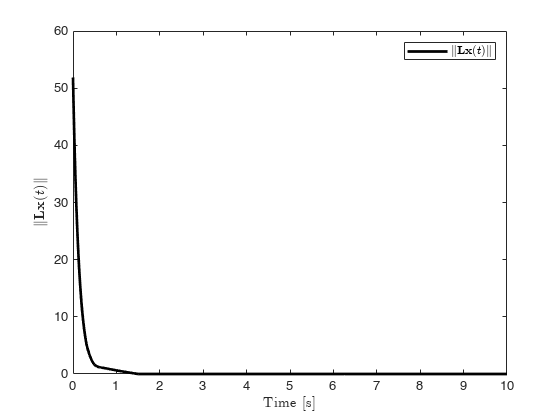


figure
hold on;
plot(t,e,'-k','LineWidth',2);
xlabel('Time [s]','Interpreter','latex'); 
ylabel('$\|\mathbf{Lx}(t)\|$', 'interpreter','latex');
box on;
legend({'$\|\mathbf{Lx}(t)\|$'}, 'interpreter', 'latex');

function dx = smc_consensus(t,x)
    global L d n
    k = 2; k0 = 1;
    dist = kron(ones(n,1),[0.5*sin(t/2); 0.5*cos(t/2); 0]);
    for i=1:n
        dist(3*i-2:3*i,1) = dist(3*i-2:3*i,1) + [0.5*sin(i*t); 0; t/(3*t+i)];
    end
    u1 = -L*x;
    dx = k0*u1 + k*sign(u1) + dist;
end
